% calibration data
distance = [10, 15, 20, 25, 30, 35, 40]; 
adc = [598, 541, 518, 508, 479, 467, 443];
p = polyfit(adc, distance, 2); 
fprintf('Distance = %.4e * ADC^2 + %.4e * ADC + %.4e\n', p(1), p(2), p(3));

Distance = 8.0649e-04 * ADC^2 + -1.0429e+00 * ADC + 3.4478e+02


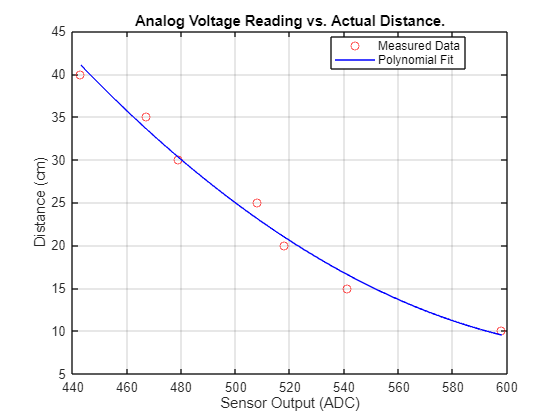

x = linspace(min(adc), max(adc), 100); y = polyval(p, x);
plot(adc, distance, 'ro', x, y, 'b-') 
xlabel('Sensor Output (ADC)'); ylabel('Distance (cm)'); 
legend("Measured Data", "Polynomial Fit", 'Location', 'best'); 
title("Analog Voltage Reading vs. Actual Distance."); 
grid on;

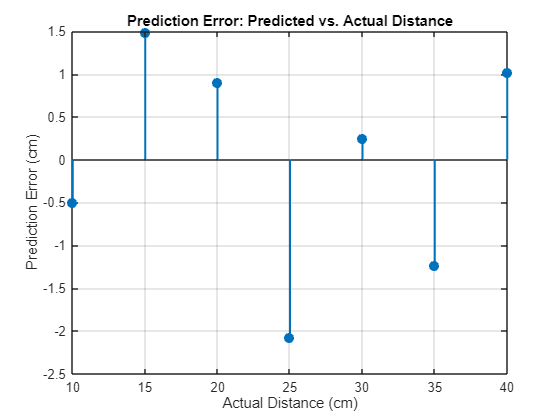

% actual distances
actual_distance = [10, 15, 20, 25, 30, 35, 40];

% predicted distances
predicted_distance= [9.5, 16.48, 20.9, 22.92, 30.25, 33.76, 41.02];
% errors
error = predicted_distance - actual_distance;

figure;
stem(actual_distance, error, 'filled', 'LineWidth', 1.5);
xlabel('Actual Distance (cm)');
ylabel('Prediction Error (cm)');
title('Prediction Error: Predicted vs. Actual Distance');
grid on;

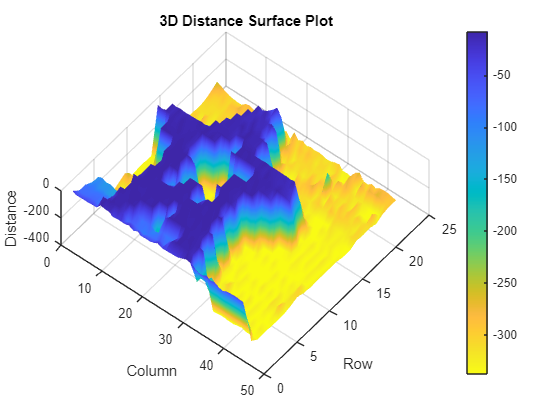

% raw sensor data
star_data = [
    474, 428, 429, 435, 432, 439, 438, 637, 544, 545, 459, 474, 474, 473, 506, 438, 488, 430, 438, 434, 457, 514, 455, 457, 464, 467, 480, 522, 632, 564, 483, 420, 421, 475, 420, 441, 390, 372, 406, 415, 419, 411, 408, 209, 42;
    352, 348, 352, 359, 359, 333, 589, 591, 664, 601, 589, 504, 356, 380, 361, 342, 321, 341, 344, 350, 387, 348, 420, 562, 613, 604, 594, 606, 543, 160, 218, 214, 142, 7, 7, 13, 10, 7, 7, 12, 19, 7, 7, 8, 7;
    344, 337, 332, 337, 341, 347, 325, 493, 602, 602, 599, 614, 599, 395, 340, 347, 361, 306, 324, 364, 333, 332, 332, 457, 651, 606, 676, 590, 589, 524, 135, 191, 154, 60, 8, 19, 7, 20, 7, 19, 8, 20, 7, 20, 12;
    292, 310, 287, 289, 274, 267, 282, 624, 613, 601, 669, 615, 608, 609, 593, 661, 192, 120, 469, 645, 629, 610, 673, 609, 608, 603, 599, 578, 138, 7, 38, 9, 12, 19, 8, 26, 7, 19, 8, 19, 8, 9, 8, 7, 7;
    280, 295, 271, 279, 253, 246, 242, 242, 639, 613, 690, 602, 610, 610, 611, 658, 594, 611, 145, 534, 634, 623, 689, 601, 677, 600, 622, 596, 578, 200, 14, 24, 46, 8, 8, 19, 7, 26, 8, 19, 8, 19, 7, 19, 8;
    80, 55, 74, 13, 7, 7, 155, 599, 690, 611, 634, 610, 611, 612, 631, 651, 610, 607, 626, 609, 607, 606, 674, 613, 608, 625, 606, 246, 8, 19, 7, 7, 14, 19, 7, 7, 11, 7, 7, 12, 7, 32, 20, 55, 8;
    19, 60, 70, 57, 31, 7, 13, 7, 546, 641, 647, 605, 610, 604, 612, 614, 616, 673, 602, 609, 625, 607, 657, 598, 682, 606, 610, 603, 287, 22, 7, 19, 7, 19, 9, 19, 7, 24, 8, 19, 7, 27, 12, 26, 20;
    42, 8, 7, 7, 7, 8, 20, 9, 704, 619, 611, 620, 332, 82, 395, 697, 633, 629, 613, 182, 126, 470, 648, 627, 607, 608, 412, 68, 7, 7, 13, 19, 7, 8, 7, 7, 7, 14, 7, 7, 13, 11, 16, 34, 38;
    69, 93, 13, 19, 7, 16, 7, 15, 7, 712, 612, 688, 615, 574, 163, 7, 599, 633, 694, 596, 205, 97, 221, 652, 628, 677, 599, 489, 68, 12, 7, 7, 7, 8, 7, 7, 8, 19, 8, 20, 8, 19, 14, 43, 21;
    7, 12, 7, 19, 14, 18, 8, 27, 641, 671, 613, 608, 610, 188, 7, 7, 7, 8, 92, 88, 34, 635, 689, 612, 606, 594, 559, 158, 7, 10, 7, 19, 8, 19, 7, 19, 7, 7, 8, 7, 7, 8, 13, 9, 16;
    12, 7, 7, 7, 19, 7, 19, 8, 711, 616, 622, 607, 608, 610, 428, 78, 7, 19, 7, 18, 157, 37, 653, 638, 611, 605, 632, 594, 623, 306, 70, 7, 7, 7, 7, 7, 8, 7, 19, 13, 8, 8, 19, 8, 19;
    13, 14, 8, 178, 610, 620, 616, 595, 596, 622, 596, 541, 236, 36, 18, 8, 19, 8, 19, 152, 8, 8, 645, 628, 610, 610, 588, 650, 589, 580, 555, 474, 211, 7, 7, 13, 19, 7, 20, 7, 19, 8, 19, 8, 19;
    8, 12, 7, 262, 603, 587, 587, 636, 585, 595, 610, 546, 173, 38, 19, 7, 25, 8, 19, 8, 235, 8, 19, 7, 147, 641, 618, 596, 594, 605, 573, 630, 555, 532, 482, 200, 18, 7, 18, 8, 18, 7, 25, 8, 17;
    625, 538, 615, 553, 603, 566, 638, 585, 587, 584, 595, 660, 589, 635, 565, 177, 8, 8, 624, 603, 669, 587, 639, 591, 586, 601, 562, 633, 581, 562, 549, 555, 531, 493, 187, 8, 11, 11, 22, 8, 18, 8, 19, 8, 18;
    19, 60, 617, 550, 619, 556, 572, 570, 579, 642, 575, 651, 581, 592, 593, 591, 556, 72, 19, 644, 607, 616, 595, 588, 588, 644, 570, 574, 568, 559, 569, 532, 585, 294, 119, 51, 8, 7, 9, 16, 14, 20, 7, 8, 7;
    8, 37, 37, 41, 43, 7, 47, 83, 137, 212, 366, 660, 583, 576, 577, 571, 531, 584, 657, 579, 573, 557, 222, 83, 46, 69, 57, 17, 36, 61, 43, 20, 16, 31, 13, 7, 7, 21, 16, 26, 14, 20, 12, 7, 7;
    10, 29, 30, 49, 30, 55, 14, 57, 30, 65, 61, 85, 553, 588, 576, 573, 632, 549, 637, 567, 575, 565, 550, 265, 16, 19, 30, 32, 38, 8, 31, 37, 16, 19, 7, 7, 8, 7, 31, 21, 16, 20, 26, 37, 32;
    20, 12, 7, 8, 7, 8, 17, 7, 16, 8, 19, 9, 313, 589, 567, 544, 539, 599, 537, 544, 394, 65, 7, 7, 13, 7, 10, 65, 48, 36, 31, 25, 38, 46, 32, 30, 54, 36, 47, 42, 38, 31, 20, 42, 26;
    37, 48, 14, 69, 16, 30, 7, 24, 8, 19, 8, 19, 12, 19, 635, 549, 545, 538, 548, 525, 610, 437, 97, 8, 7, 7, 55, 42, 51, 61, 78, 25, 43, 12, 58, 40, 26, 53, 35, 53, 31, 48, 30, 36, 30;
    32, 31, 31, 35, 21, 36, 45, 37, 26, 60, 51, 25, 33, 51, 133, 586, 502, 566, 467, 206, 10, 16, 38, 42, 26, 36, 22, 31, 54, 29, 59, 51, 186, 37, 20, 37, 26, 37, 17, 54, 13, 7, 7, 70, 16;
    36, 37, 32, 32, 32, 41, 38, 37, 38, 25, 56, 57, 36, 21, 52, 37, 87, 419, 539, 382, 83, 57, 20, 36, 36, 37, 38, 31, 32, 29, 31, 55, 30, 78, 54, 68, 39, 27, 26, 25, 17, 7, 7, 13, 42;
    60, 42, 41, 48, 35, 54, 56, 74, 52, 37, 20, 37, 41, 32, 37, 43, 16, 24, 74, 30, 64, 34, 53, 41, 55, 41, 25, 37, 36, 20, 25, 46, 7, 7, 78, 52, 16, 75, 41, 73, 64, 80, 62, 47, 50;
    91, 74, 55, 42, 36, 32, 32, 56, 65, 51, 38, 37, 35, 64, 36, 59, 35, 44, 10, 79, 36, 51, 32, 42, 36, 41, 36, 27, 31, 42, 48, 16, 19, 8, 63, 83, 37, 32, 55, 42, 61, 65, 64, 56, 48;
];


% calibration equation
Distance = -(8.0649e-04 * star_data.^2 - 1.0429e+00 * star_data + 344.78);


% 3d surface plot
figure;
surf(Distance);
xlabel('Column'); ylabel('Row'); zlabel('Distance');
title('3D Distance Surface Plot');
colorbar;
colormap(flipud(parula));
shading interp;
view([39 75]);

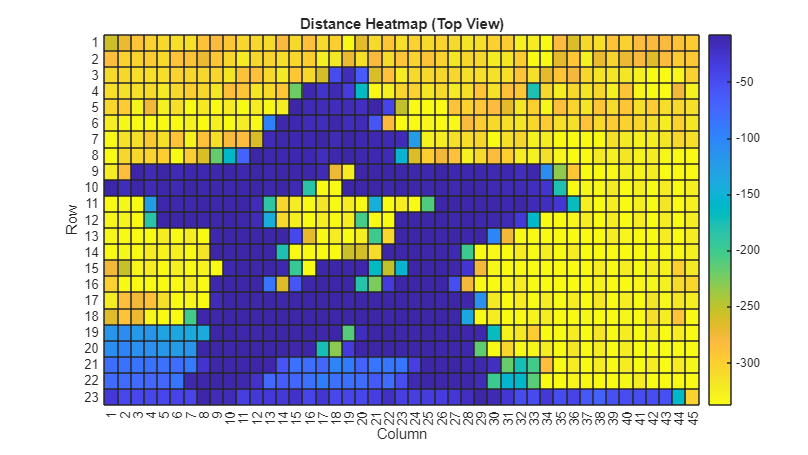


% 2d top view (heatmap)
figure;
figure('Units','normalized','Position',[0.2 0.2 0.6 0.6]); 
h = heatmap(flipud(Distance));
h.XDisplayLabels = string(1:size(Distance,2));
h.YDisplayLabels = string(1:size(Distance,1));
h.Colormap = flipud(parula);
h.Title = 'Distance Heatmap (Top View)';
h.XLabel = 'Column';
h.YLabel = 'Row';

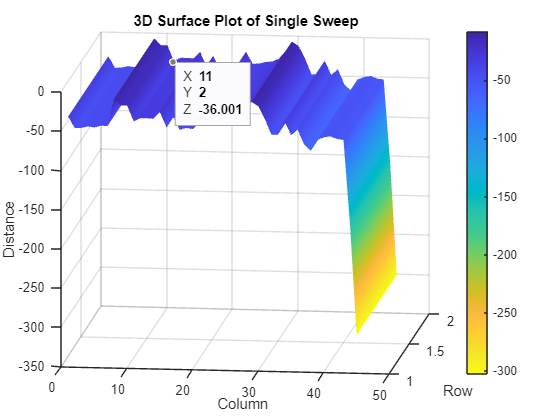

% Raw sensor data
star_data = [474, 428, 429, 435, 432, 439, 438, 637, 544, 545, 459, 474, 474, 473, 506, 438, 488, 430, 438, 434, 457, 514, 455, 457, 464, 467, 480, 522, 632, 564, 483, 420, 421, 475, 420, 441, 390, 372, 406, 415, 419, 411, 408, 209, 42];

Distance = -(8.0649e-04 * star_data.^2 - 1.0429 * star_data + 344.78);
DistanceMatrix = [Distance; Distance]; % 2 rows

figure;
surf(DistanceMatrix);
xlabel('Column'); ylabel('Row'); zlabel('Distance');
title('3D Surface Plot of Single Sweep');
colorbar;
colormap(flipud(parula));
shading interp;
view([39 75]);

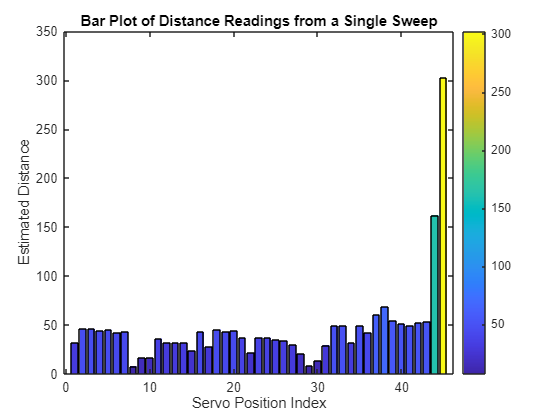



% Calibration equation (positive distances)
Distance = 8.0649e-04 * star_data.^2 - 1.0429 * star_data + 344.78;

% Create bar plot
figure;
b = bar(Distance, 'FaceColor', 'flat');

% Apply color mapping
b.CData = Distance'; % each bar gets a color based on its height
colormap(parula);    % use parula colormap
colorbar;            % show color scale

xlabel('Servo Position Index');
ylabel('Estimated Distance');
title('Bar Plot of Distance Readings from a Single Sweep');